# TD 6: Exercice 2 - Opération de convolution

close all;
clearvars;
syms u t a RC

sig1= @(t) rectangularPulse(0,a,t)

sig1 = function_handle with value:
    @(t)rectangularPulse(0,a,t)


sig2= @(t) 1/RC*exp(-t/RC)*heaviside(t)

sig2 = function_handle with value:
    @(t)1/RC*exp(-t/RC)*heaviside(t)


## 
$$y\left (t \right )=\int_{-\infty}^{+\infty}x\left ( \tau \right )h\left ( t- \tau \right )d\tau$$


## Avec le retournement de h(t)

x(t)=sig1(t) 

$$x(t) = \mathrm{rectangularPulse}\left(0,a,t\right)$$

h(t)=sig2(t)

$$h(t) = \frac{{\mathrm{e}}^{-\frac{t}{\mathrm{RC}}}\,\mathrm{heaviside}\left(t\right)}{\mathrm{RC}}$$

hc(t)=h(u-t)

$$hc(t) = \frac{\mathrm{heaviside}\left(u-t\right)\,{\mathrm{e}}^{\frac{t-u}{\mathrm{RC}}}}{\mathrm{RC}}$$

disp('Expression litterale de y(t)=x(t)*h(t)')

Expression litterale de y(t)=x(t)*h(t)


y1= int(x*hc, t, -inf,+inf)

$$y1 = \mathrm{heaviside}\left(u-a\right)\,\left({\mathrm{e}}^{\frac{a-u}{\mathrm{RC}}}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-\frac{u}{\mathrm{RC}}}-1\right)$$

Assignation de valeurs pour RC et a pour le tracé de la convolution


RCval=0.5 

RCval = 0.5000

aval=4

aval = 4

hp=subs(h,RC,RCval)

$$hp(t) = 2\,{\mathrm{e}}^{-2\,t}\,\mathrm{heaviside}\left(t\right)$$

xp=subs(x,a,aval)

$$xp(t) = \mathrm{rectangularPulse}\left(0,4,t\right)$$

yp=subs(y1,[a, RC],[aval, RCval])

$$yp = \mathrm{heaviside}\left(u-4\right)\,\left({\mathrm{e}}^{8-2\,u}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-2\,u}-1\right)$$


figure;
tiledlayout(3,1)
nexttile;
fplot(xp,'b','LineWidth',2)
ylim([-0.1 1.1]);
xmax=4*RCval+aval+0.1

xmax = 6.1000

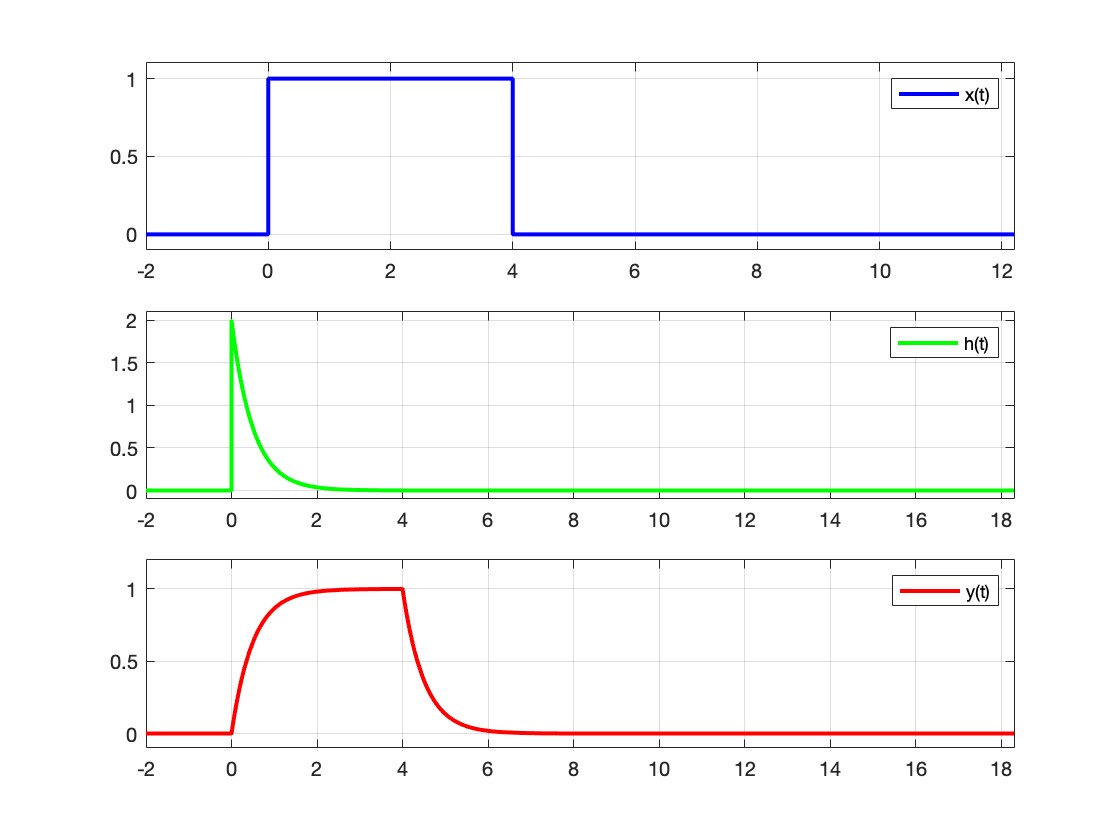

xlim([-2 2*xmax])
legend('x(t)');
grid on;

nexttile;
fplot(hp,'r','LineWidth',2)
grid on;
legend('h(t)');
ylim([-0.1 1/RCval+0.1]);
xlim([-2 3*xmax])


nexttile;
fplot(yp,'g','LineWidth',2)
grid on;
legend('y(t)');
ylim([-0.1 1.2]);
xlim([-2 3*xmax])

## 
$$y\left (t \right )=\int_{-\infty}^{+\infty}h\left ( \tau \right )x\left ( t- \tau \right )d\tau$$


## Avec le retournement de x(t)

x(t)=sig1(t) 

$$x(t) = \mathrm{rectangularPulse}\left(0,a,t\right)$$

h(t)=sig2(t)

$$h(t) = \frac{{\mathrm{e}}^{-\frac{t}{\mathrm{RC}}}\,\mathrm{heaviside}\left(t\right)}{\mathrm{RC}}$$

xc(t)=x(u-t)

$$xc(t) = \mathrm{rectangularPulse}\left(0,a,u-t\right)$$

disp('Expression litterale de y(t)=x(t)*h(t)')

Expression litterale de y(t)=x(t)*h(t)


y2= int(h*xc, t, -inf,+inf)

$$y2 = \mathrm{heaviside}\left(u-a\right)\,\left({\mathrm{e}}^{\frac{a-u}{\mathrm{RC}}}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-\frac{u}{\mathrm{RC}}}-1\right)$$

Assignation de valeurs pour RC et a pour le tracé de la convolution


RCval=0.5 

RCval = 0.5000

aval=4

aval = 4

hp=subs(h,RC,RCval)

$$hp(t) = 2\,{\mathrm{e}}^{-2\,t}\,\mathrm{heaviside}\left(t\right)$$

xp=subs(x,a,aval)

$$xp(t) = \mathrm{rectangularPulse}\left(0,4,t\right)$$

yp=subs(y2,[a, RC],[aval, RCval])

$$yp = \mathrm{heaviside}\left(u-4\right)\,\left({\mathrm{e}}^{8-2\,u}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-2\,u}-1\right)$$


figure;
tiledlayout(3,1)
nexttile;
fplot(xp,'b','LineWidth',2)
ylim([-0.1 1.1]);
xmax=4*RCval+aval+0.1

xmax = 6.1000

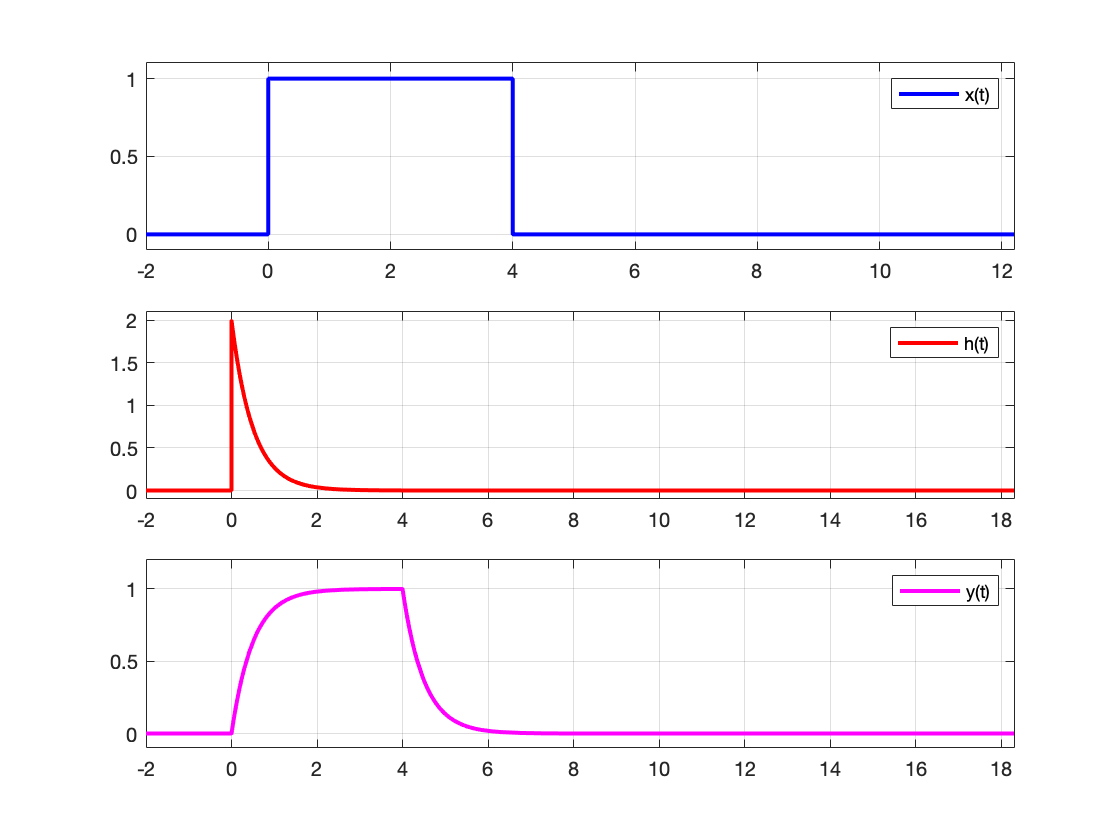

xlim([-2 2*xmax])
legend('x(t)');
grid on;

nexttile;
fplot(hp,'r','LineWidth',2)
grid on;
legend('h(t)');
ylim([-0.1 1/RCval+0.1]);
xlim([-2 3*xmax])


nexttile;
fplot(yp,'m','LineWidth',2)
grid on;
legend('y(t)');
ylim([-0.1 1.2]);
xlim([-2 3*xmax])

# Approfondissement

## Reprise du calcul de la convolution à l'aide de l'intercorrelation

$R_{xy}\left ( \tau \right )=\int_{-\infty}^{+\infty}x\left ( t \right )y\left ( t- \tau \right )dt$   => il suffit de prendre y(-t) pour avoir x(t)*y(t)

figure;
tiledlayout(2,1)
nexttile;% Calcul del'intercorrelation Ryx
x=sig1(t) 

$$x = \mathrm{rectangularPulse}\left(0,a,t\right)$$

y(t)=sig2(-t)

$$y(t) = \frac{\mathrm{heaviside}\left(-t\right)\,{\mathrm{e}}^{t/\mathrm{RC}}}{\mathrm{RC}}$$

yc=y(t-u)

$$yc = \frac{\mathrm{heaviside}\left(u-t\right)\,{\mathrm{e}}^{\frac{t-u}{\mathrm{RC}}}}{\mathrm{RC}}$$

disp('Expression litterale de Rxyinv = x*y')

Expression litterale de Rxyinv = x*y


Rxyinv= int(x*yc, t, -inf,+inf);
Rxyinv = simplify(Rxyinv ,'Steps',50)

$$Rxyinv = \mathrm{heaviside}\left(u-a\right)\,\left({\mathrm{e}}^{\frac{a-u}{\mathrm{RC}}}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-\frac{u}{\mathrm{RC}}}-1\right)$$

$R_{yx}\left ( \tau \right )=\int_{-\infty}^{+\infty}y\left ( t \right )x\left ( t- \tau \right )dt$ => il suffit de prendre x(-t) pour avoir x(t)*y(t)

x(t)=sig1(-t) 

$$x(t) = \mathrm{rectangularPulse}\left(0,a,-t\right)$$

y(t)=sig2(t)

$$y(t) = \frac{{\mathrm{e}}^{-\frac{t}{\mathrm{RC}}}\,\mathrm{heaviside}\left(t\right)}{\mathrm{RC}}$$

xc=x(t-u)

$$xc = \mathrm{rectangularPulse}\left(0,a,u-t\right)$$

disp('Expression litterale de Ryxinv = x*y' )

Expression litterale de Ryxinv = x*y


Ryxinv= int(y*xc, t, -inf,+inf);
Ryxinv = simplify(Ryxinv ,'Steps',50)

$$Ryxinv = \mathrm{heaviside}\left(u-a\right)\,\left({\mathrm{e}}^{\frac{a-u}{\mathrm{RC}}}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-\frac{u}{\mathrm{RC}}}-1\right)$$



RCval=0.5 

RCval = 0.5000

aval=4

aval = 4

Rxyinvp=subs(Rxyinv,[a, RC],[aval, RCval])

$$Rxyinvp = \mathrm{heaviside}\left(u-4\right)\,\left({\mathrm{e}}^{8-2\,u}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-2\,u}-1\right)$$


Ryxinvp=subs(Ryxinv,[a, RC],[aval, RCval])

$$Ryxinvp = \mathrm{heaviside}\left(u-4\right)\,\left({\mathrm{e}}^{8-2\,u}-1\right)-\mathrm{heaviside}\left(u\right)\,\left({\mathrm{e}}^{-2\,u}-1\right)$$

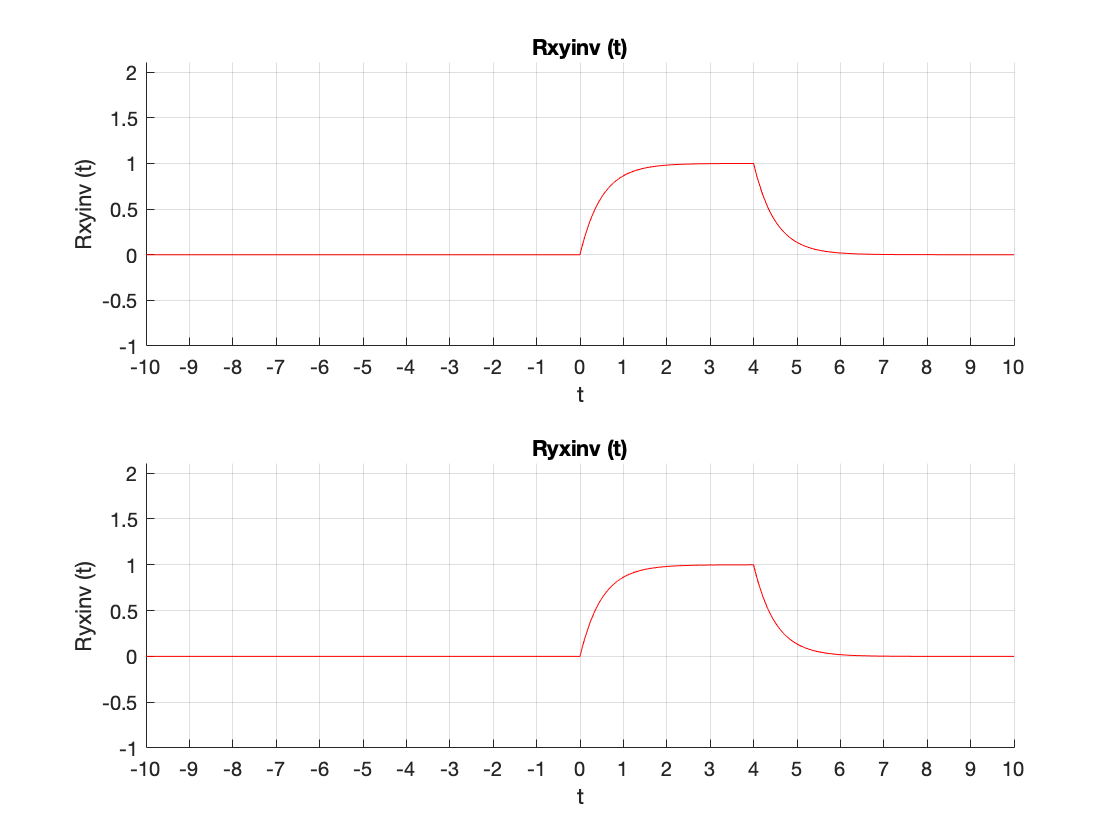


xlim([-10 10]);
ax = gca;
S = sym(ax.XLim(1):1:ax.XLim(2));       % graduation pour fonction classique
%S = sym(ax.XLim(1):pi:ax.XLim(2));     % graduation pour fonction trigo
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
grid on;
hold on;
fplot(Rxyinvp,'r')
ylim([-1 2.1]);
%legend;
xlabel('t');
ylabel('Rxyinv (t)');
title('Rxyinv (t)');

nexttile;% Calcul del'intercorrelation Ryx

xlim([-10 10]);
ax = gca;
S = sym(ax.XLim(1):1:ax.XLim(2));       % graduation pour fonction classique
%S = sym(ax.XLim(1):pi:ax.XLim(2));     % graduation pour fonction trigo
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);
grid on;
hold on;
fplot(Ryxinvp,'r')
ylim([-1 2.1]);
%legend;
xlabel('t');
ylabel('Ryxinv (t)');
title('Ryxinv (t)');